# Principal Components Analysis (PCA)

*Shira Lupkin - 2020*

*BK updated - April 2023*

Pricipal Component Analysis, PCA, is popular linear dimensionality technique in neuroscience. The object of PCA is to define a set of vectors/directions (i.e., principal components) in feature-space that capture the largest amount of variance in the data. We can then project the data onto these vectors for a lower-dimensional representation of the data that preserves the covariance of the original data. 

For example, consider the extracellular recording of action potentials. Each neuron produces an action potential with a speciifc shape that depends on intrinsic factors such as the Na- and K-channels expressed in the neuron as well as extrinsic factors such as the distance from the electrode tip to the neuron's soma.  An electrode will typically record action potentials from multiple nearby neurons and researchers often like to sort these action potentials into groups corresponding to individual neurons. Modern electrophysiology recordings systems can record 40,000 samples per second, hence a single action potential (~ 1 ms) is represented by 40 numbers. Hence the sorting of action potentials ("spike sorting) requires assessing the similarity of waveforms desribed by a sequence of 40 numbers. 

That is a difficult problem; there are simply too many ways in which two lists of 40 numbers can differ. So the first step in this process is to reduce the dimensionality of the data from the 40 dimensions to something more manageable (2 or 3) using PCA. Before we go into this, let's start with a simpler (albeit abstract) example in which the dataset has 2 dimensions. Let's call them Variable 1 and Variable 2.  

## Explanation of PCA Procedure

### Step 1: Center (and Scale) the Data

Since PCA is only concerned with the variance of the data, the first step to pre-processing data for PCA is to center the data by subtracting the mean for each input variable. This removes the influence of the mean of a given variable from biasing the overall results. Note in figure below, that this operation shifts the data to the center but the points are still in the same positions relative to each other. 

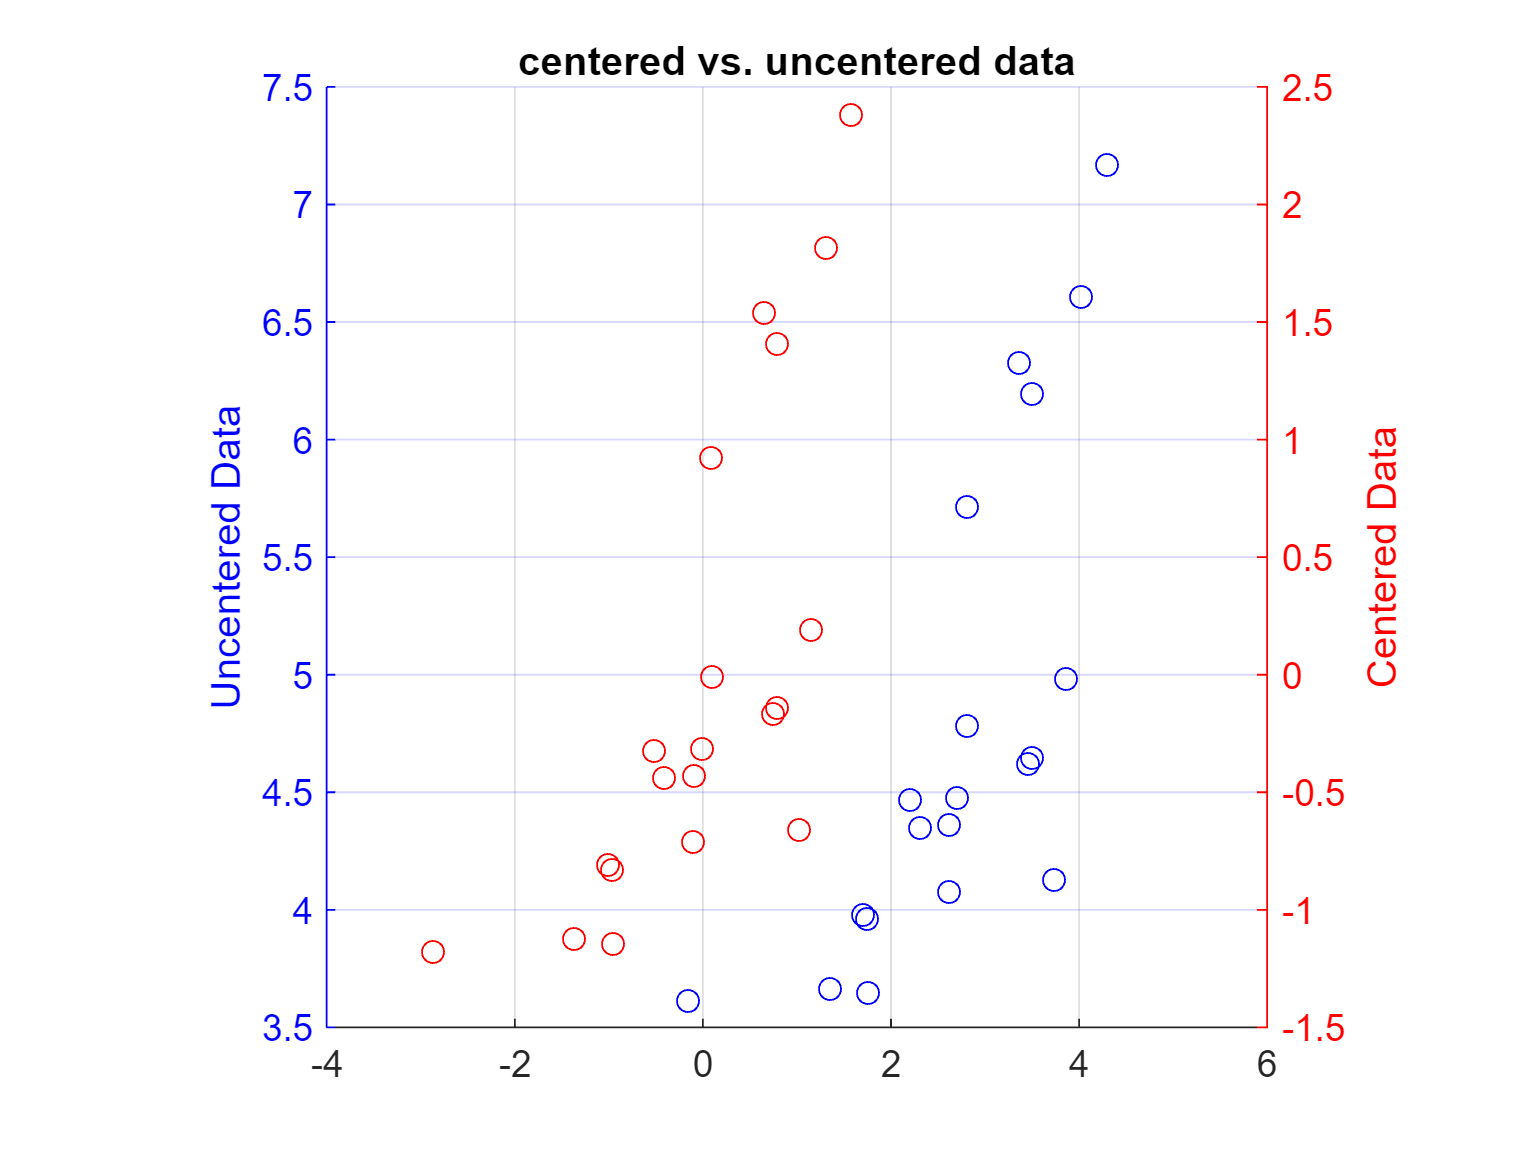

load ../data/toyData
figure(1)
clf
centered1 = x1-mean(x1); 
centered2 = x2-mean(x2); 

% plot the centered and uncentered datasets on the same graph
leftColor = [0 0 1];
rightColor = [1 0 0];
set(gcf,'defaultAxesColorOrder',[leftColor; rightColor]);
yyaxis left
scatter(x1,x2,'bo')
ylabel('Uncentered Data')
yyaxis right
scatter(centered1,centered2,'ro')
ylabel ('Centered Data')
title('centered vs. uncentered data')
pbaspect([1 1 1])
grid on

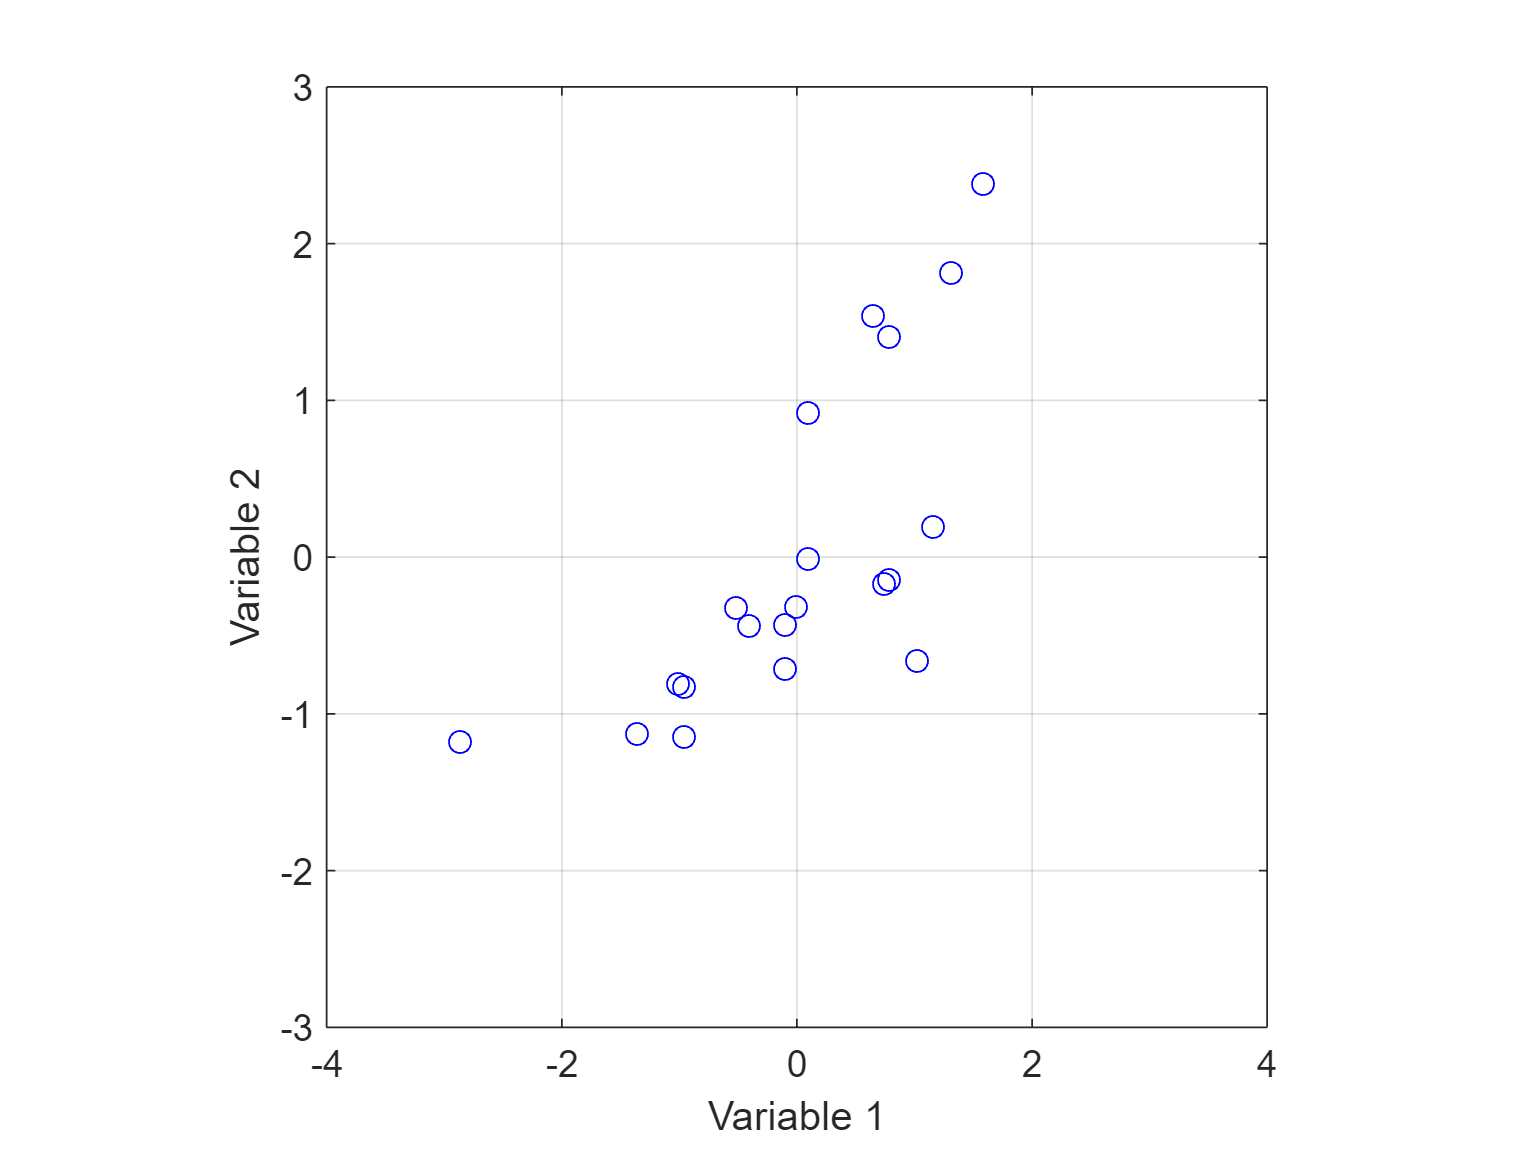

figure(2)
clf
scatter(centered1,centered2,'bo')
xlabel ('Variable 1')
ylabel ('Variable 2')
ylim([-3 3])
xlim([-4 4])
pbaspect([1 1 1])
grid on
box on

The `pca` function in Matlab centers the data by default, but it is important to understand why this step is conducted. If your variables are on the same scale of measurement, then centering your data is the only preprocessing necessary before you apply PCA. However, if they are not on the same scale that data *also *needs to be scaled so that everything is on the same scale. These steps can be done in sequence, or at once by computing the zscore for each data point ($z_i \;=\left(\frac{x_i -\bar{x} }{\sigma_x }\right)$). If you have to scale your data, do it before plugging it into the pca function and set the 'centered' argument to 'false'. (`pca(zData,'centered',false)`).  

### Step 2: Find the Principal Components

#### Finding Principal Component (PC1)

The first principal component is a vector that points towards the direction(s) of maximum variation in your data. In a figure you can eyeball this direction by looking at the data point cloud and guess which direction has the largest spread (=variance).

There are a few procedures for finding these principal components. The two most common are Eigenvalue Decomposition  and Singular Value Decomposition (SVD). Both are beyond the scope of this course, but if you are interested see: [Gilbert Strang's Lecture on SVD](https://www.youtube.com/watch?v=rYz83XPxiZo).  In Matlab, the `pca` function defaults to using SVD. In brief, finding the principal components using SVD amounts to:

- Plotting a line that runs through the origin (0,0)

- Projecting each data point onto the line

- Calculating the distance between the projected points and the origin

- Squaring these distances (to avoid negative numbers)

- Summing the squared distances.

- Rotate the line and repeat Steps 2-5 until you have found the vector that maximizes the summed squared-distances. 

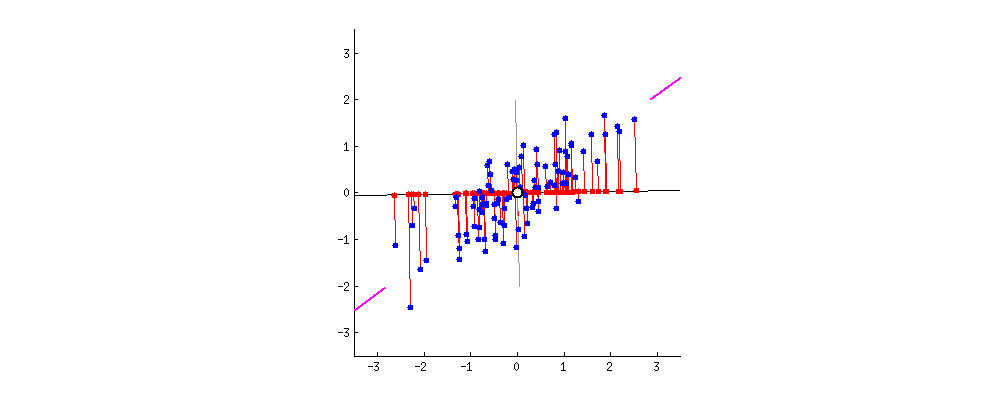

[Source](https://builtin.com/data-science/step-step-explanation-principal-component-analysis)

The direction (i.e. vector) that maximizes the sum of squared distances is called *Principal Component 1 (PC1) *. The nomenclature tends to get a bit confusing. The word principal component is sometimes used for the vector, and sometimes for the projection of the data point onto that vector (which is, technically, the correct usage as the projection is the component). These vectors are also called eigenvectors. Matlab calls the vectors 'coefficients' and the projections 'loading scores'; they are the first and second output argument of the `pca` function.

#### Finding PCs 2+

The total number of potential PCs is determined by the number of variables in your data. For instance, in our toy example, there are 2 variables and therefore 2 principal components. The specific component numbers (e.g., PC1, PC2, PC3, etc.) correspond, in decreasing order, to the amount of variance explained by that PC. In other words, PC1 explains the most variance, PC2 the second most, etc.  Importantly, these vectors are not correlated to each other (i.e., they are orthogonal). 

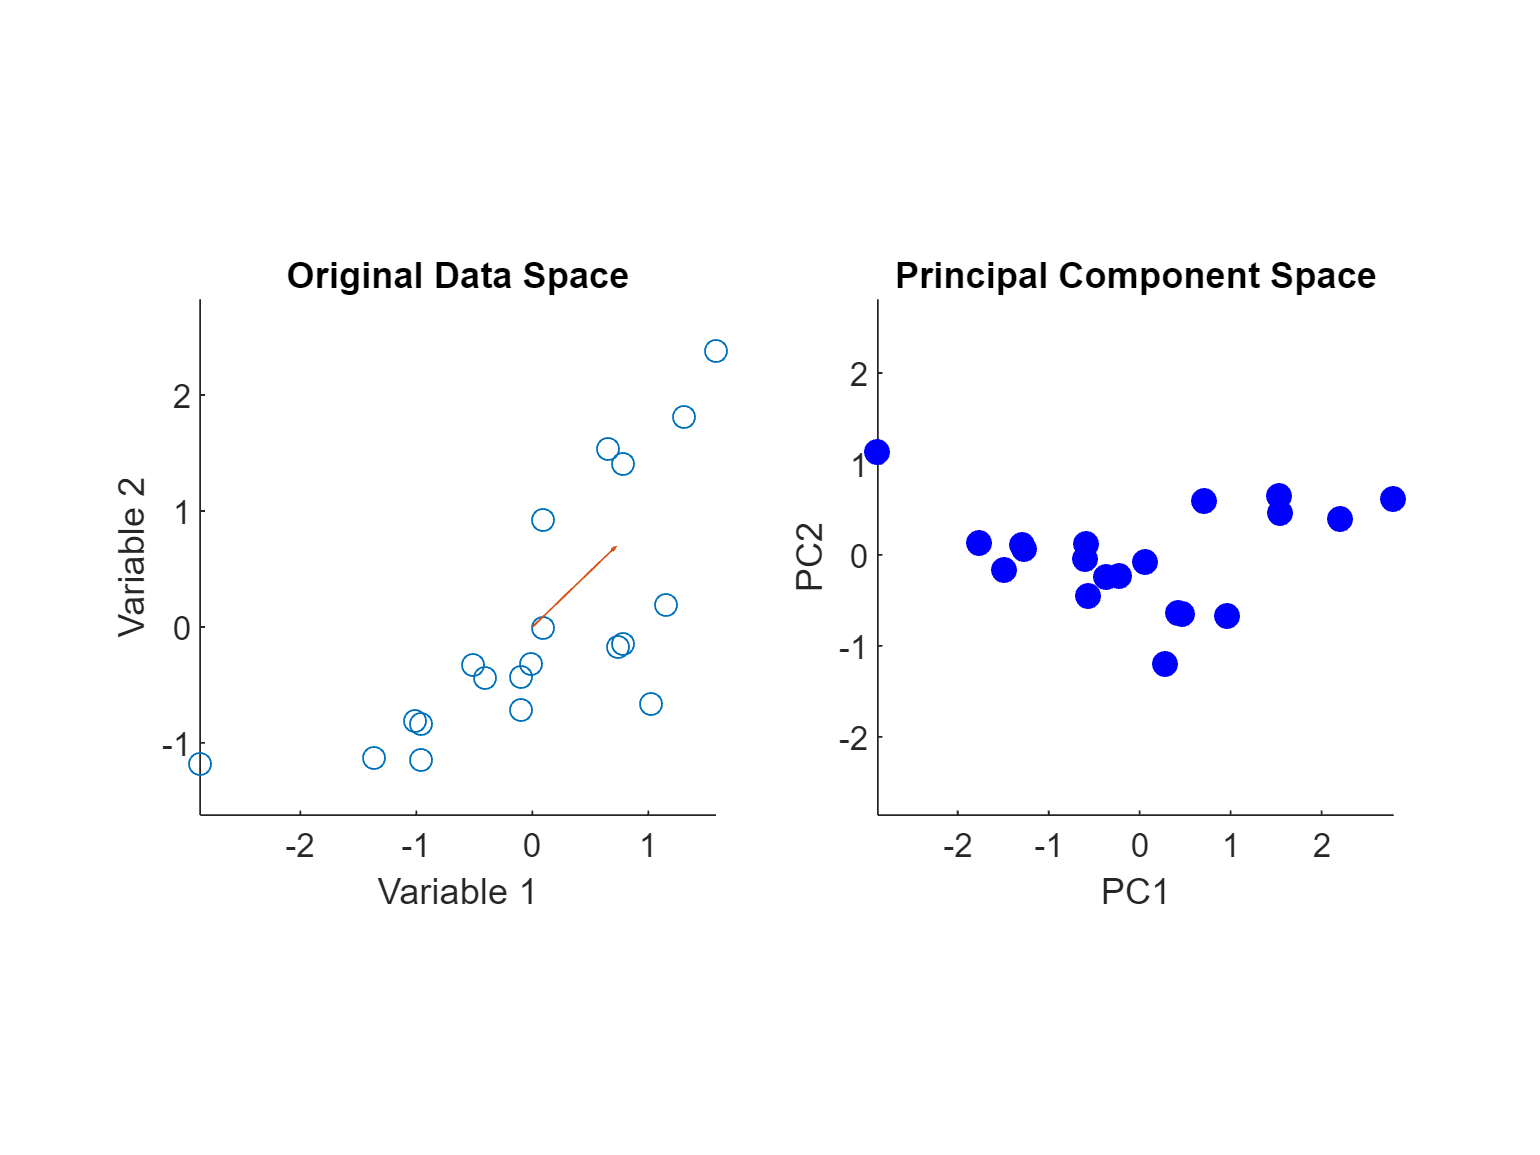

% let's run PCA and plot projected points onto the two PCs
[pc,loadingScores, ~,~,varianceExplained] = pca([centered1,centered2],'Centered',false);
figure(4)
clf


subplot(1,2,1)
% plot the orginal (centered) data 
scatter(centered1,centered2,'o'); hold on
%  Show the first PC as a vector
firstPC = pc(:,1);
quiver(0,0,firstPC(1),firstPC(2),"off")
axis equal
xlabel 'Variable 1'
ylabel 'Variable 2'
title 'Original Data Space'
pbaspect([1 1 1])

subplot(1,2,2)
scatter(loadingScores(:,1),loadingScores(:,2),50,'b',"filled")
xlabel 'PC1'
ylabel 'PC2'
title 'Principal Component Space'
axis equal
pbaspect([1 1 1])

The left panel shows the original data representation and the red arrow identifies the direction in that 2D space along which the variance is maximal (i.e. it is the direction associated with the first principal component, or PC1, for short). The right panel shows **exactly the same data **on two new axes.  

The horizontal axis represents PC1 (direction of largest variance) and vertical is PC2 (next largest variance). The scales on the axes are the same and that allows you to see immediately that there is a lot of variation horizontally, and very little vertically. The change of data representation going from left to the right panel is lossless; you can descibe each data point as some combination of Variabel 1 and Variable 2, or as the combination of PC1 and PC2.  However, the representation in the right panel makes it clear that knowing PC1 is more informative than knowing PC2. So , if you had to chose a single PC to represent a datapoint you would pick PC1; that PC explains most of the variance in the data set. In the next section, we will quantify the amount of variance explained by each of the components. 

### Step 3: The Variance Explained by each PC

It is important to realize that PCA is a lossless operation;  no information is lost by describing the data in terms of the principal components and we can freely move back and forth between the original variables and the description in PCA space. Dimensionality *reduction *requires chosing a subset of principal components. With PCA this choice is usually based on variance that each component explains. The `pca` function returns this as its 5th output argument. 

varianceExplained

varianceExplained =    86.3466
   13.6534


This supports what we saw in the previous figure. Namely that PC1 accounts for a lot (86%) of the variance in the data, while PC2 accounts for the remaining 14%. So, to reduce the dimensionality of this two-dimensional data set, we can chose to represent the data by the first principal component. This means we loose some  information, but, in this case, this reduced description still captures 86% of the variance in the original set.  Chosing the number of principal components to use is somewhat arbitrary -  in some applications you may chose to pick whatever number is required to capture 90% of the variance, in others you may pick only 2 components to simplify visualization.  A graph of explained variance against the component number is often instructive; that curve often rises rapidly (showing that the first few components capture most of the information) and then only gradually (additional components don't add much). In such cases it may make sense to include the components on the steep part of the explained variance graph, but not those on the shallow part. 

In an extreme case, the explained variance graph could be a straight line. That means each component contributes equally to the variance and implies that PCA will not help you to reduce the dimensionality of the data set. 

## Spike Sorting Using PCA

One example of how PCA is used in neuroscience is spike sorting: organizing spike waveforms into groups that have a similar shape.  As discussed above, a waveform is typically represented by 40 numbers per spike. We could use our biophysical knowledge of spikes to reduce the dimensionality of this data set. For instance, we know that each spike will have a peak, and a trough, and we could therefore represent each spike by the difference between the peak and trough (i.e. the "size" of the spike). That is a reduction from 40 dimensions (samples) to a single dimension (size). But this is ad-hoc; there may well be distinct neurons with identically sized spikes, and we could be missing out on some differences that are not so easily pre-specified. 

PCA lets the data decide which dimensions (features) are informative  and which are not. 

#### The Data

The data for this demonstration can be found in the file called `spikeWaveForms.mat`. The file contains two variables:

- `samples` is a vector containing the sampling points referenced to the time point at which a spike was detected (e.g., detection time = 0). 

- `spikes` contains [samples x number of waveforms] matrix with the voltage for each waveform at each sampling point. 

So, in this data set we have 40 (samples) features per waveform in the original space, based on those 40 features we would like separate certain shapes (waveforms), but comparing 40 numbers across 3328 waveforms is too complex. Instead, we ask whether we can reduce the complexity of the description to something lower dimensional, using PCA.

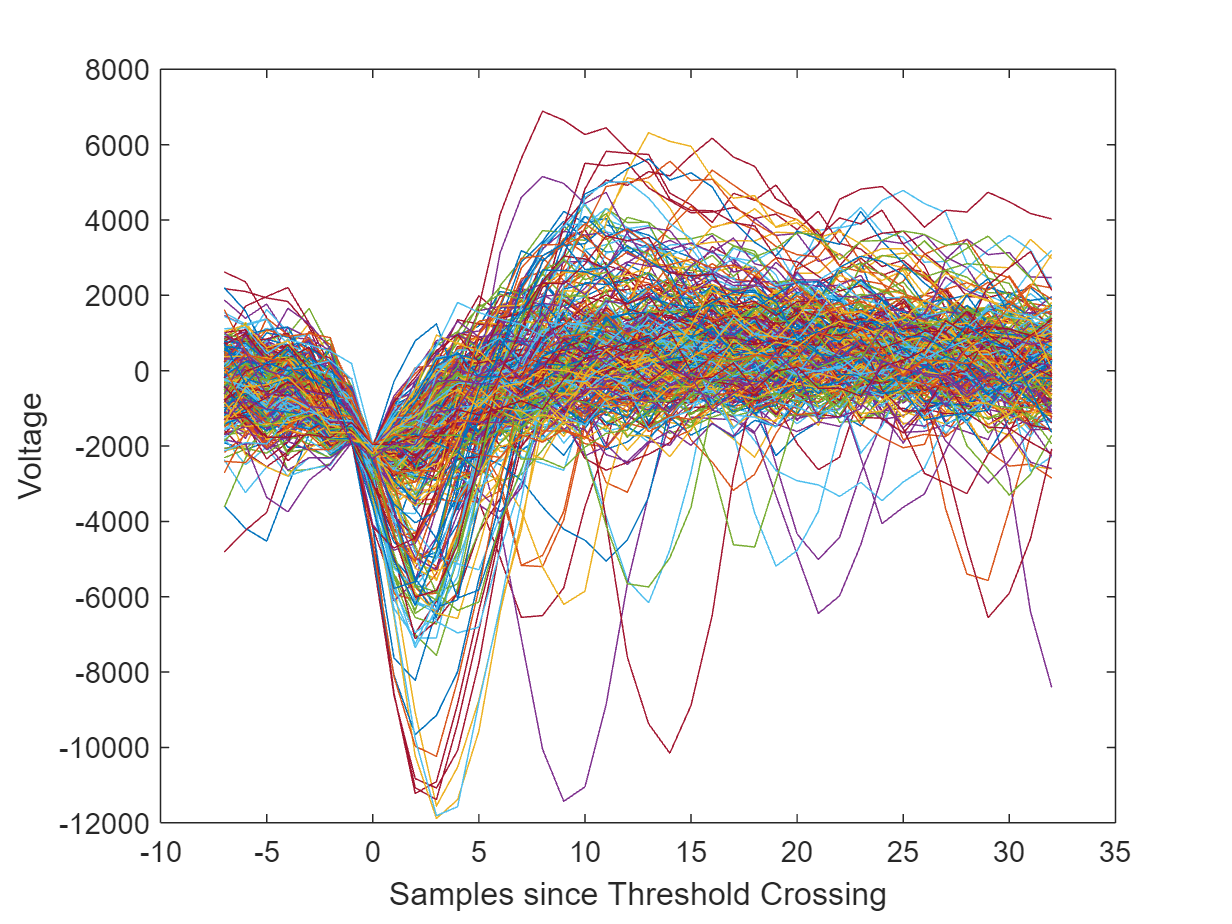

load ../data/spikeWaveForms     
figure(6);
clf
% visualize the data
plot(samples,spikes(:,1:10:end));% Plotting only every 10th waveform to save time.
xlabel 'Samples since Threshold Crossing'
ylabel 'Voltage'

In this representation, each waveform is represented by 40 numbers. Another way of thinking about these data is that each waveform is a point in a 40-dimensional space. You may already see that there are some waveforms with a very deep  trough, one set with intermediate troughs, and then some very shallow ones. Maybe these correspond to spikes from distinct neurons, but this is hard to see in this representation. Reducing the dimensionality using PCA may provide some clarity.

% compute PCA
[components,projections,~,~,explainedVariance] = pca(spikes');

As discussed above, the `explainedVariance `gives some insight into how useful PCA is for a given dataset.  Here we plot the cumulative sum of the explained variance for each component:

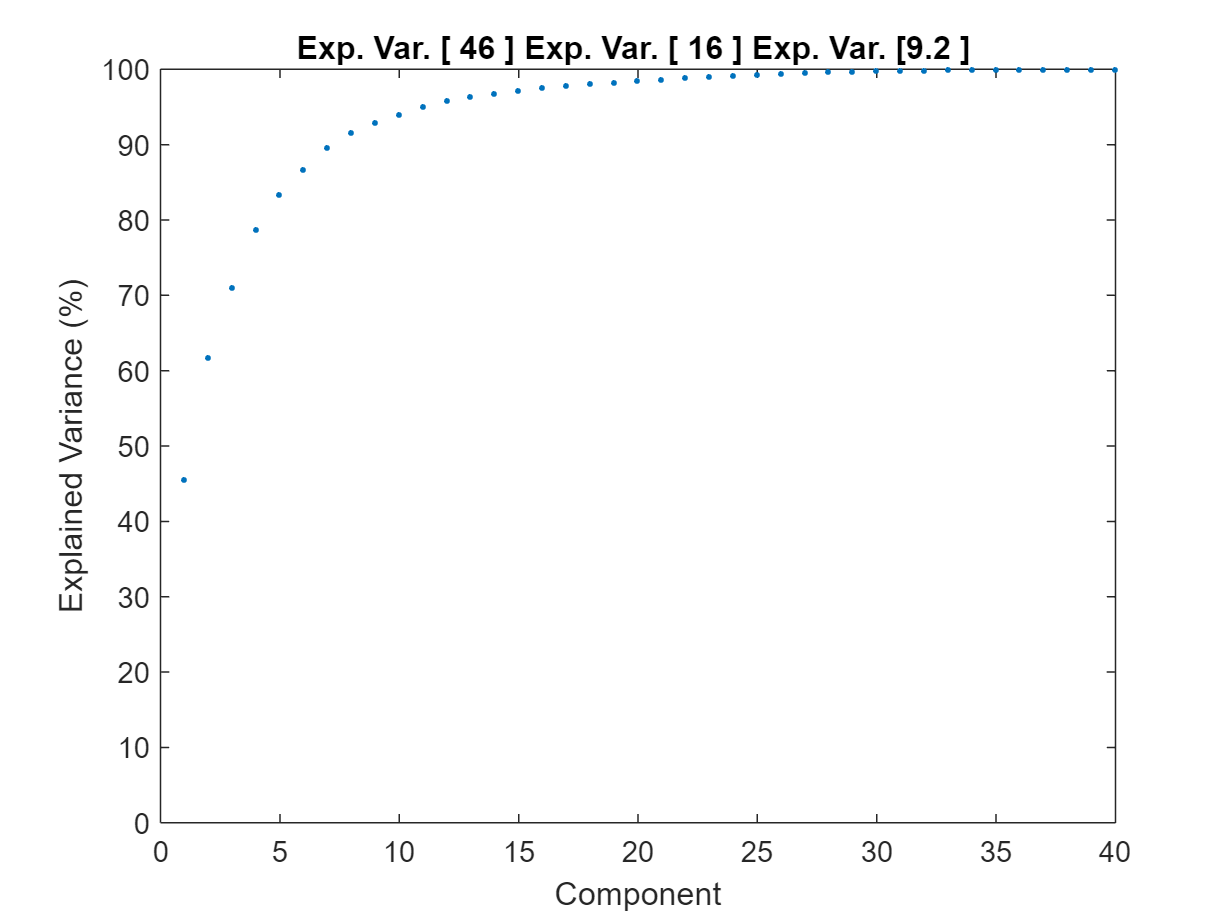

clf;
plot(cumsum(explainedVariance),'.');
set(gca,'YLim',[0 100])
xlabel 'Component'
ylabel 'Explained Variance (%)'
title(sprintf('Exp. Var. [%3.2g ] ',explainedVariance(1:3)))

Clearly, the variance explained does not increase linearly:  the first component accounts for 46% of the variance, the second adds 16%, and the third an additional 9%. Subsequent components add additional variance explained, but it is not unreasonable to focus on the first 2 or 3 components because this reduces the dimensionality (from 40 to  2 or 3) while still capturing more than 60%  or even 70% of the variance in the original set. Note that there are no hard rules here;  you could add more components, but this would make it harder to visualize and analyze the data (e.g. with a clustering algorithm,which tend to get lost in high dimensional spaces).

For visualization, we pick the first two components: 

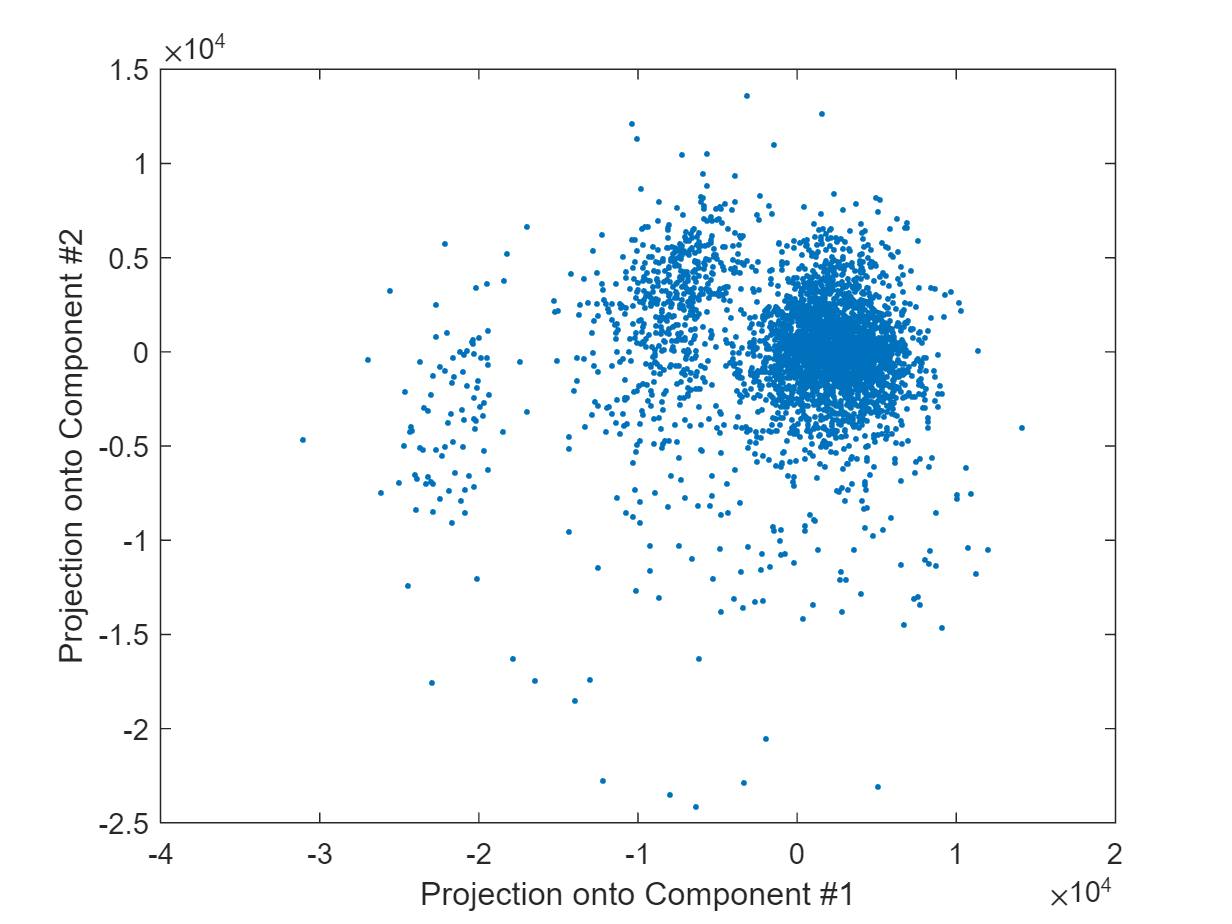

% Show each spike as a projection on the first two PCs
clf
plot(projections(:,1),projections(:,2),'.')
xlabel 'Projection onto Component #1'
ylabel 'Projection onto Component #2'

This uses only two numbers (PC1 and PC2) to represent the enitre set of spike waveforms. While this transformation loses some information (38% of the variance),  it immediately shows that there are three clusters of data points in this PC1/PC2 space (which may correspond to three neurons).  The next step in spike sorting is to group these (apparent) clusters, but that is a classification problem that is distinct from PCA). 

Before we move to classification, let's see what these components are. At the start of this section we discussed how one could do dimensionality reduction based on some known features (size: peak-trough). That has the advantage that the lower-dimensional representation is easy to interpret;  a spike with a large value in this "size" space is a spike with a small amplitude.  So in that case, the dimensions can be interpreted as real physcial properties (which may be linked to some biophysical mechanism that produces small or large amplitude spikes). It is important to realize that this is NOT the case for PCA. The components are only determined by the variance they explain and need not correspond to any real properties of neurons. To illustrate this, let's look at the first three components:

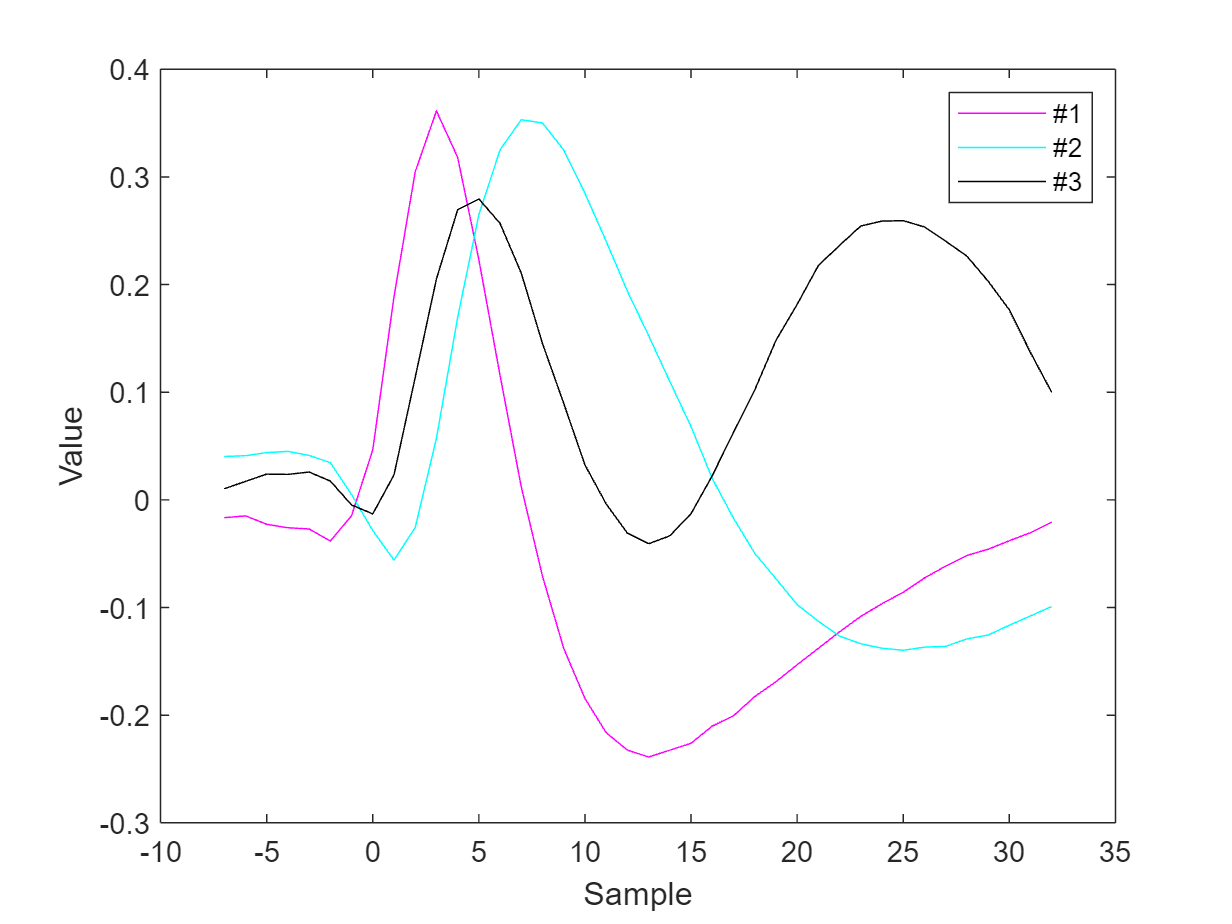

% Show the first three principal components
clf; 
plot(samples,components(:,1),'m');
hold on ;
plot(samples,components(:,2),'c')
plot(samples,components(:,3),'k')
xlabel 'Sample'
ylabel 'Value'
legend('#1','#2','#3');

By definition, these principal components show the "directions" in the high-dimensional original space (40 samples = 40 dimensional) that explain most variance. The 'projection onto component #1' in the previous figure quantifies how much a spike looks like the component (1 means an exact match, -1 means that the spike exactly matched the component with a flipped sign, and +10 would be a spike that looks exactly like the component but is 10 times as large). (More formally, the projection is the inner product of the spike with the component).

While it is tempting to interpret the magenta curve as a spike waveform of a unit, this would be incorrect. It is an abstract shape (a direction in the 40 dimensional space), some waveforms look a lot like this, others do not. Maybe it is easier to phrase this with reference to PC3 (black); the fact that this is a principal component does not mean that action potentials show this strange wiggle, only that a linear combination of this wiggle together with the #1 and #2 shapes describes all waveforms quite well (more precisely: "captures 71% of the variance"). 

### Classification using K-means

PCA has helped to reduce the dimensionality and the visualization above shows that there appear to be 3 clusters. Many spike-sorting packages use this 2D (or a 3D) representation to select clusters manually.  For instance, in Matlab you could use `ginput `to draw boundaries around a cluster in  PC1/PC2 space and assign the waveforms inside the boundary to a putative neuron.

With increasing channel counts such manual clustering becomes very cumbersome and more automated clustering algorithms have been developed. For illustration purposes we'll use one of the simplest algorithms, called K-Means clustering. This is a simple but effective techinique that is explained here : [Explanation of K-means Clustering](https://www.youtube.com/watch?v=4b5d3muPQmA&feature=youtu.be).

We tell the `kmeans `algorithm how many clusters to create, and which dimensions to use (here, the projections onto the first two components visualized above).

nrClusters= 3;  
color = 'rgb';
dimensions = 1:2;
[unit,c] =kmeans(projections(:,dimensions),nrClusters,'Replicates',10);


Using this classification by `kmeans`, we plot the projections onto the components using colors to identify each unit, as well as the average waveform of each unit.

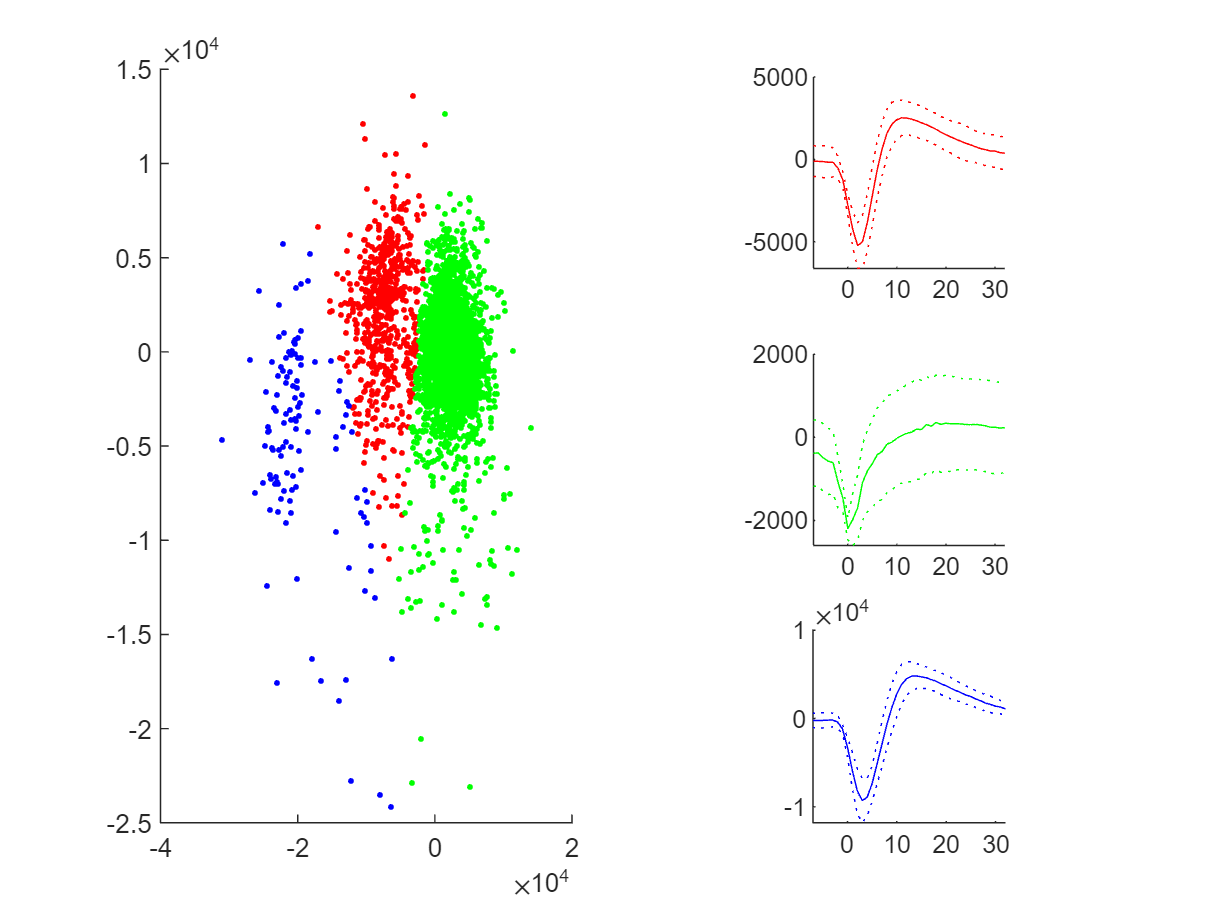

clf;
xlabel 'Sample'
ylabel 'Average Waveform'
for i=1:3
    IN = unit==i;
    subplot(3,2,[1 3 5]); 
    hold on
    plot(projections(IN,1),projections(IN,2),[color(i) '.']);
     
    m   = mean(spikes(:,IN),2);
    sd = std(spikes(:,IN),1,2);
    
    subplot(3,2,(i-1)*2+2);
    hold on
    plot(samples,m,color(i));
    plot(samples,m+sd,[color(i) ':']);
    plot(samples,m-sd,[color(i) ':']);
    pbaspect([1 1 1])
end

You can see that kmeans is not perfect (probably a manual sorter would have assigned some data points differently)), but it does a pretty good job classifying the clusters in this 2-dimensional PCA space. This illustrates how the lower dimensional representation (some information is lost) is nevertheless useful for the purpose of classification. You can experiment with this by passing additional component projecttions to the alogrithm and see whether that imrpoves the separation between the clusters. One of the main disadvantages of k-means is that you have to tell it the number of clusters in advance and it will always separate the data into that many clusters. 

The panels on the right show the average waveforms for each of the clusters. The error bars (dashed lines) reflect the variation in the waveform within a cluster. Narrow errorbars suggest that the waveforms really arise from a single unit ("good isolation") while wide error bars suggest that those spikes are probably generated by multiple neurons ("multi-unit or hash"). 

## References and Additional Resources

[StatQuest PCA Step-by-Step](https://www.youtube.com/watch?v=FgakZw6K1QQ&feature=youtu.be)

[ISLR Unsupervised Learning Playlist](https://www.youtube.com/playlist?list=PLAOUn-KLSAVMOah3Vz100xM0eTLdj5ovq)

[ISLR PDF--See Chapter 10](http://faculty.marshall.usc.edu/gareth-james/ISL/ISLR%20Seventh%20Printing.pdf)